info=imfinfo('catto.jpg')

info = struct with fields:
           Filename: '/MATLAB Drive/IVP/catto.jpg'
        FileModDate: '18-Jul-2023 17:09:33'
           FileSize: 17378
             Format: 'jpg'
      FormatVersion: ''
              Width: 400
             Height: 400
           BitDepth: 24
          ColorType: 'truecolor'
    FormatSignature: ''
    NumberOfSamples: 3
       CodingMethod: 'Huffman'
      CodingProcess: 'Progressive'
            Comment: {}


image_size=info.FileSize

image_size = 17378

image_width=info.Width

image_width = 400

image_height=info.Height

image_height = 400

color_depth=info.BitDepth

color_depth = 24

color_type=info.ColorType

color_type = 'truecolor'

sample_number = info.NumberOfSamples

sample_number = 3

coding_Method = info.CodingMethod

coding_Method = 'Huffman'

coding_process = info.CodingProcess

coding_process = 'Progressive'

image=imread('catto.jpg')

image = 400×400×3 uint8 array
image(:,:,1) =

   199   198   195   193   194   196   199   201   200   199   197   194   191   189   189   189   189   189   187   185   185   188   193   198   197   196   193   190   188   189   190   192   189   190   191   191   191   192   193   194   194   195   194   193   192   192   193   194   194   194   195   196   197   195   193   191   196   195   199   203   199   190   187   189   194   194   195   197   200   202   202   201   203   203   202   200   197   195   194   194   198   197   195   194   193   191   188   185   188   190   191   190   188   189   193   197   194   193   192   194   197   197   194   190   198   200   201   200   197   194   194   194   190   190   190   191   193   195   197   199   196   198   197   191   187   188   192   193   195   193   192   190   189   188   188   189   186   189   192   194   193   192   190   190   188   184   180   181   185   191   193   194   198   201   202   198   195   195   196

imwrite(image,'newcatto.png','png')
imshow(image)
invimg = 255-image

invimg = 400×400×3 uint8 array
invimg(:,:,1) =

    56    57    60    62    61    59    56    54    55    56    58    61    64    66    66    66    66    66    68    70    70    67    62    57    58    59    62    65    67    66    65    63    66    65    64    64    64    63    62    61    61    60    61    62    63    63    62    61    61    61    60    59    58    60    62    64    59    60    56    52    56    65    68    66    61    61    60    58    55    53    53    54    52    52    53    55    58    60    61    61    57    58    60    61    62    64    67    70    67    65    64    65    67    66    62    58    61    62    63    61    58    58    61    65    57    55    54    55    58    61    61    61    65    65    65    64    62    60    58    56    59    57    58    64    68    67    63    62    60    62    63    65    66    67    67    66    69    66    63    61    62    63    65    65    67    71    75    74    70    64    62    61    57    54    53    57    60    60    

imshow(invimg)
subplot(1,2,1)
title("original image")
L=2^8

L = 256

neg=(L-1)-image

neg = 400×400×3 uint8 array
neg(:,:,1) =

    56    57    60    62    61    59    56    54    55    56    58    61    64    66    66    66    66    66    68    70    70    67    62    57    58    59    62    65    67    66    65    63    66    65    64    64    64    63    62    61    61    60    61    62    63    63    62    61    61    61    60    59    58    60    62    64    59    60    56    52    56    65    68    66    61    61    60    58    55    53    53    54    52    52    53    55    58    60    61    61    57    58    60    61    62    64    67    70    67    65    64    65    67    66    62    58    61    62    63    61    58    58    61    65    57    55    54    55    58    61    61    61    65    65    65    64    62    60    58    56    59    57    58    64    68    67    63    62    60    62    63    65    66    67    67    66    69    66    63    61    62    63    65    65    67    71    75    74    70    64    62    61    57    54    53    57    60    60    59    

subplot(1,2,2),
imshow(neg)
title("Negative image")
x=imread('catto.jpg')

x = 400×400×3 uint8 array
x(:,:,1) =

   199   198   195   193   194   196   199   201   200   199   197   194   191   189   189   189   189   189   187   185   185   188   193   198   197   196   193   190   188   189   190   192   189   190   191   191   191   192   193   194   194   195   194   193   192   192   193   194   194   194   195   196   197   195   193   191   196   195   199   203   199   190   187   189   194   194   195   197   200   202   202   201   203   203   202   200   197   195   194   194   198   197   195   194   193   191   188   185   188   190   191   190   188   189   193   197   194   193   192   194   197   197   194   190   198   200   201   200   197   194   194   194   190   190   190   191   193   195   197   199   196   198   197   191   187   188   192   193   195   193   192   190   189   188   188   189   186   189   192   194   193   192   190   190   188   184   180   181   185   191   193   194   198   201   202   198   195   195   196   195  

imshow(x)
x=rgb2gray(imread('catto.jpg'))

x = 400×400 uint8 matrix
   193   192   189   187   188   190   193   195   194   193   191   188   185   183   183   183   185   185   183   181   181   184   189   194   194   193   190   187   185   186   187   189   185   186   187   187   187   188   189   190   190   191   190   189   188   188   189   190   190   190
   193   191   189   187   187   189   192   193   191   190   189   187   185   184   184   184   187   186   185   183   183   187   192   196   195   193   189   186   184   184   185   187   185   186   187   188   188   188   189   189   191   191   190   189   188   189   191   193   194   195
   191   190   188   186   186   188   190   191   188   187   186   185   185   186   187   188   190   189   188   187   188   191   195   199   195   193   189   185   183   183   184   185   186   187   187   188   189   189   189   189   190   190   189   188   188   190   193   195   198   199
   189   188   187   186   186   187   189   190   187   187   186   186

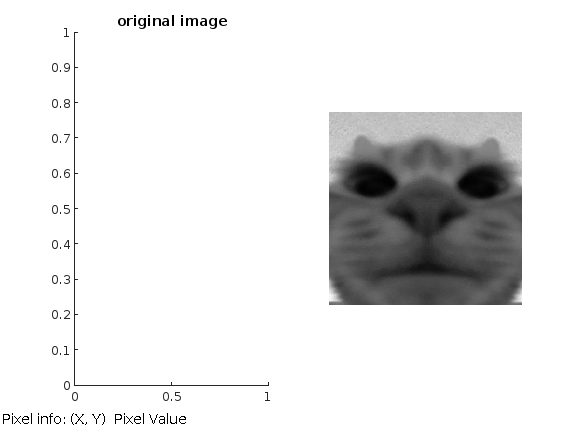

imshow(x)
impixelinfo

T=input('Enter something:')

T = 150

[row col]=size(x)

row = 400

col = 400

IM_BW=zeros(row,col)

IM_BW =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     

for i=1:row
        for j=1:col
              if(x(i,j)>T)
                  IM_BW(i,j)=1
              else
                  IM_BW(i,j)=0
              end
        end
end